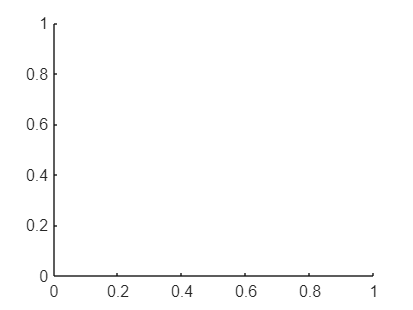

clear all
clc
hold on

%Definición de los parámetros, en este caso el PWP201
Voc=16.799;
Isc=1.0317;
Imp=0.92550;
Vmp=12.4929;
T=45;
Ns=36;
G=1000;
%lectura curva del módulo, en este caso del PWP201
Ie= transpose(xlsread('PWP201.xlsx','C3:C25'));
Ve= transpose(xlsread('PWP201.xlsx','B3:B25'));
%constantes físicas
q=1.60218*10^(-19);
K=1.38065*10^(-23);
%Calculo Vth por Ns
Vth=Ns*K*(T+273.15)/q;
%creación vectores con soluciones
Rs=[];
Rsh=[];
n=[];
%cálculo valores iniciales
ng=(Voc-Vmp-Vth)/(Vth*log(Isc/(Isc-Imp)));
ns=(Voc-Vmp)/(Vth*log(Vmp/Vth));
np=(Isc-Imp)*(Vmp-Vth)/(Isc*Vth);
no=[ng,ns,np];
n(1)=min(no);
Rs(1)=(Voc-Vmp-n(1)*Vth*log(Vmp/(n(1)*Vth)))/Imp;
Rsh(1)=((Vmp-Imp*Rs(1))*Vmp-n(1)*Vth*Vmp)/((Vmp-Imp*Rs(1))*(Isc-Imp)-n(1)*Vth*Imp)-Rs(1);
%Inicio iteraciones
i=1;
%error en tanto por ciento
err=0.0001;
%Se define un error inicial para empezar el bucle, siendo este siempre
%mayor que err
err1=1;
while abs(err1)>err
   ng=(Voc-Vmp-Imp*Rs(i))/(Vth*log((Isc*(Rs(i)+Rsh(i))-Voc)/((Isc-Imp)*(Rs(i)+Rsh(i))-Vmp)));
   np=(Isc-Imp)*(Vmp-Imp*Rs(i))/(Vth*Isc);
   alfa=(Vmp+n(i)*Vth-Imp*Rs(i))/(n(i)*Vth);
   beta=(Isc*(Rs(i)+Rsh(i))-Voc)/(Isc*(Rs(i)+Rsh(i))-2*Vmp);
   ns=(Voc-Vmp)/(Vth*log(alfa*beta));
   nk=[ng np ns];
   n(i+1)=double(min(nk));
   alfa=(Vmp+n(i+1)*Vth-Imp*Rs(i))/(n(i+1)*Vth);
   Rs(i+1)=(Voc-Vmp-[n(i+1)*Vth*log(alfa*beta)])/Imp;
   Rsh(i+1)=((Vmp-Imp*Rs(i+1))*Vmp-n(i+1)*Vth*Vmp)/((Vmp-Imp*Rs(i+1))*(Isc-Imp)-n(i+1)*Vth*Imp)-Rs(i+1);
   i=i+1;
   err1=100*abs(Rs(i)-Rs(i-1))/Rs(i);
end
fprintf('el valor de Rs es %fΩ',Rs(i));

el valor de Rs es 1.783170Ω

fprintf('el valor de Rsh es %fΩ' ,Rsh(i));

el valor de Rsh es 1023.374927Ω

fprintf('el valor de n es %f',n(i));

el valor de n es 1.130829

fprintf('número de iteraciones es %d',i-1);

número de iteraciones es 9

%valores definitivos
Rs1=Rs(i);
Rsh1=Rsh(i);
n1=n(i);
%fotocorriente y corriente del diodo
Iph=Isc*(Rs(i)+Rsh(i))/Rsh(i);
Io=(Isc*(Rs(i)+Rsh(i))-Voc)/Rsh(i)*exp(-Voc/(n(i)*Vth));
fprintf('el valor de Iph es %fA' ,Iph);

el valor de Iph es 1.033498A

format shortE
fprintf('el valor de Io es %lo A',Io);

el valor de Io es 2.955100e-07 A


%obtención puntos curva I-V con los parámetros hallados
for i=1:length(Ve)
    syms I 
    eqn=0==-I+Iph-Io*(exp((Ve(i)+I*Rs1)/(n1*Vth))-1)-((Ve(i)+I*Rs1)/Rsh1);
    Iol=vpasolve(eqn,I);
    Isol(i)=double(Iol);
end
%Obtención del RMSE
RMSE=rmse(Isol,Ie)/Isc*100

RMSE =    1.3025e+00
